# **Wave Equation**

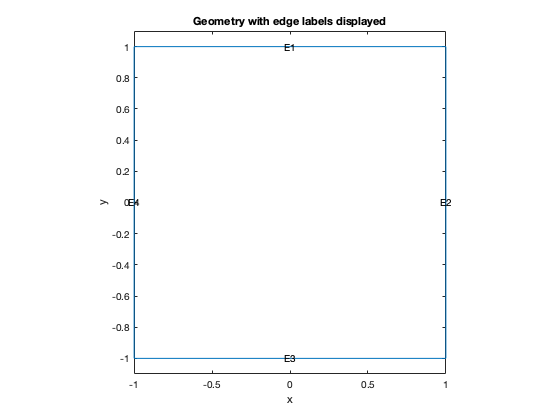



% Solve the equation

numberOfPDE = 1;
model = createpde(numberOfPDE);
geometryFromEdges(model,@squareg);
pdegplot(model,'EdgeLabels','on');
ylim([-1.1 1.1]);
axis equal
title 'Geometry with edge labels displayed';
xlabel x
ylabel y

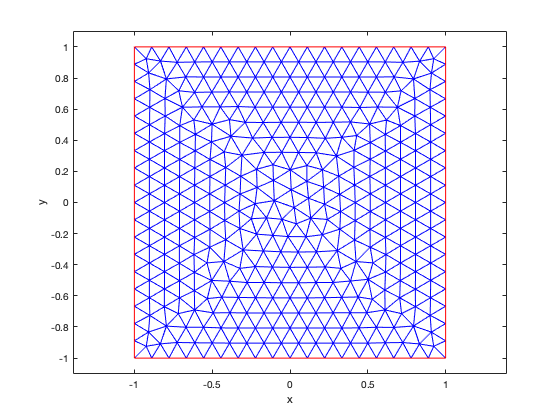


% Coeficientes
m = 1;
c = 1;
a = 0;
f = 0;

specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',f);
applyBoundaryCondition(model,'dirichlet','Edge',[4,2],'u',0);
applyBoundaryCondition(model,'neumann','Edge',([1,3]),'g',0);

generateMesh(model);
figure
pdemesh(model);
ylim([-1.1 1.1]);
axis equal
xlabel x
ylabel y


% Set initial conditions

u0 = @(location) atan(cos(pi.*location.x/2));
ut0 = @(location) 3*sin(pi.*location.x).*exp(sin(pi.*location.y/2));
setInitialConditions(model,u0,ut0);

% solve the equation

n = 31;
tlist = linspace(0,5,n);
model.SolverOptions.ReportStatistics = 'on';
result = solvepde(model,tlist);

439 successful steps
35 failed attempts
950 function evaluations
1 partial derivatives
107 LU decompositions
949 solutions of linear systems


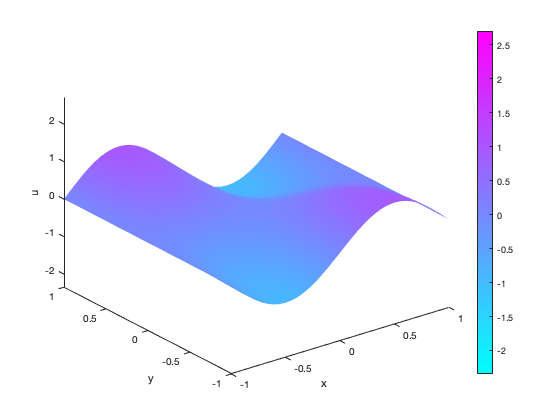

u = result.NodalSolution;

% Animation to visualize the solution

figure
umax = max(max(u));
umin = min(min(u));
for i = 1:n
    pdeplot(model,'XYData',u(:,i),'ZData',u(:,i),'ZStyle','continuous','Mesh','off');
    axis([-1 1 -1 1 umin umax]);
    caxis([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end